Mode number: 1
kx : 0.504
Error of calculation: 0.000
Power: 1.000


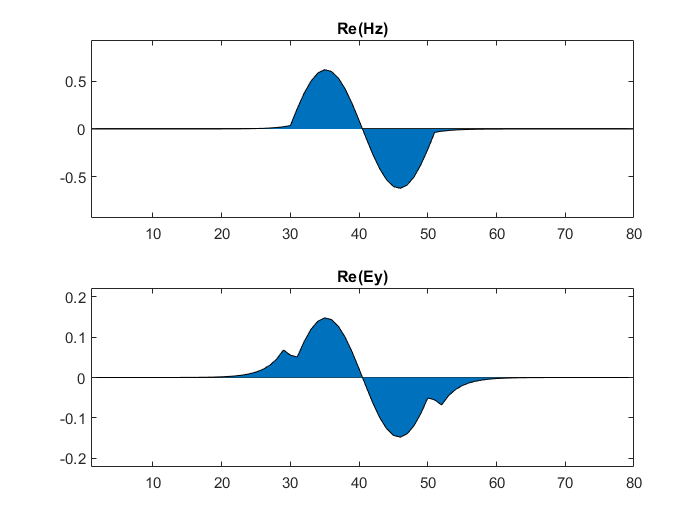

Mode number: 2
kx : 0.436
Error of calculation: 0.000
Power: 1.000


clear all;
close all;
clc

eps = ones([40 80]);
eps(:, 30:50) = 12.25;
eps(3 : end-2, 3 : end-2) = 9.0;
omega = 0.15;

prob = form(omega, eps, [1 12.25], [1 2], 'pml', 'pos');

iter_num 	sub 	phy_res 	grad
      1: 	(x) 	1.883e-03 	3.111e-02
      1: 	(y) 	1.445e-03 	2.541e-02
      2: 	(x) 	1.178e-03 	2.308e-02
      2: 	(y) 	1.018e-03 	2.358e-02
      3: 	(x) 	8.966e-04 	2.223e-02
      3: 	(y) 	8.118e-04 	2.271e-02
      4: 	(x) 	7.467e-04 	2.175e-02
      4: 	(y) 	6.955e-04 	2.221e-02
      5: 	(x) 	6.538e-04 	2.139e-02
      5: 	(y) 	6.192e-04 	2.178e-02
      6: 	(x) 	5.904e-04 	2.104e-02
      6: 	(y) 	5.653e-04 	2.135e-02
      7: 	(x) 	5.435e-04 	2.071e-02
      7: 	(y) 	5.240e-04 	2.097e-02
      8: 	(x) 	5.068e-04 	2.037e-02
      8: 	(y) 	4.905e-04 	2.060e-02
      9: 	(x) 	4.758e-04 	2.003e-02
      9: 	(y) 	4.621e-04 	2.023e-02
     10: 	(x) 	4.496e-04 	1.967e-02
     10: 	(y) 	4.378e-04 	1.985e-02
     11: 	(x) 	4.270e-04 	1.932e-02
     11: 	(y) 	4.167e-04 	1.949e-02
     12: 	(x) 	4.072e-04 	1.899e-02
     12: 	(y) 	3.983e-04 	1.916e-02
     13: 	(x) 	3.900e-04 	1.866e-02
     13: 	(y) 	3.819e-04 	1.883e-02
     14: 	(x) 	3.742e-04 	1.835e-02

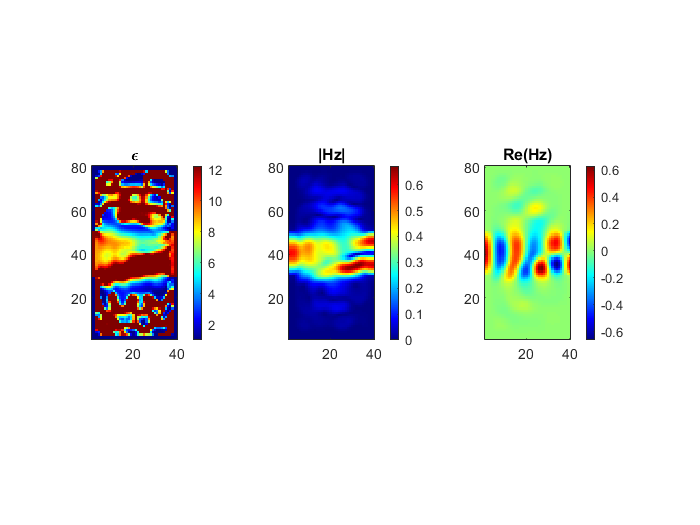

50 iterations completed in 98.0 second.


eps = optimize(prob, 50, 1e-4);

thick = [60, 60, 20, 20];
[Ex, Ey, Hz] = simulate(eps, thick, prob);

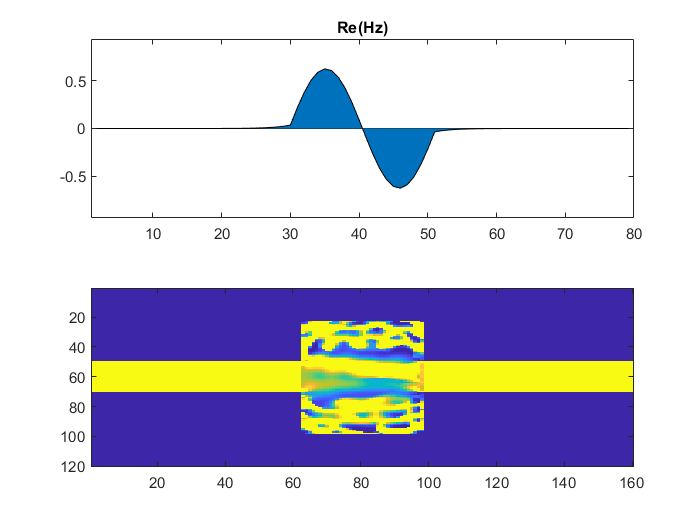

fileID = fopen('eps_f.txt', 'r');
A = fscanf(fileID, '%e %e %e', [3, inf]);
A = A';
eps = reshape(A(:, 3), [120, 160]);
imagesc(eps)